# **Implementation of Sliding Mode on a Simple First Order Sys**

clear all;close all; clc; format compact; format short; rng(123);

### **System Definition**

            $\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)+\mathit{\mathbf{u}}$,     $\left|\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} \right|\;\le \mathit{\mathbf{F}}$

     where 

                1. $\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$ is a vector valued system dynamical function.

                2. $\hat{\mathit{\mathbf{f}}}$ is equal to the middle point of system estimation of system dynamics.

                3. $\mathit{\mathbf{F}}$ is the bounded sysem estimation error function.

**    Design:**

            $n=1$          is the system order

            $\tilde{\mathit{\mathbf{x}}} =\mathit{\mathbf{x}}-{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}}$ is the tracking error

            $\mathit{\mathbf{s}}=\tilde{\mathit{\mathbf{x}}}$          is the switching surface

            $\dot{\mathit{\mathbf{s}}} =\frac{\textrm{d}}{\textrm{d}\mathbf{t}}\tilde{\mathbf{x}} =\;\dot{\mathit{\mathbf{x}}} -\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } =\hat{\mathit{\mathbf{f}}} +\mathit{\mathbf{u}}-\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } =0$              sliding surface derivative

            ${\mathit{\mathbf{u}}={\mathit{\mathbf{u}}}_{\mathbf{eq}} +\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathit{\mathbf{u}}}_{\mathbf{eq}} =-\hat{\mathit{\mathbf{f}}} +\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} }$      control signal construction

            given the Lyapunov function $\mathit{\mathbf{V}}=\frac{1}{2}\;{\mathit{\mathbf{s}}}^2$ with setting its derivative to satisfy $\mathit{\mathbf{s}}\dot{\mathit{\mathbf{s}}} \le -\eta \left|\mathit{\mathbf{s}}\right|$, (with $\eta >0$) we have:

                $\begin{array}{l}
\mathit{\mathbf{s}}\dot{\mathit{\mathbf{s}}} =\mathit{\mathbf{s}}\;\left(\mathit{\mathbf{f}}+\mathit{\mathbf{u}}-\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } \right)\\
\;\;\;\;=\mathit{\mathbf{s}}\;\left(\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} +\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right)-\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } \right)\\
\;\;\;\;=\mathit{\mathbf{s}}\left(\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} \right)-\mathit{\mathbf{s}}\;\mathit{\mathbf{k}}\;\frac{\left|\mathit{\mathbf{s}}\right|}{\mathit{\mathbf{s}}}\\
\;\;\;\;=\mathit{\mathbf{s}}\;\mathit{\mathbf{F}}-\mathit{\mathbf{k}}\;\left|\mathit{\mathbf{s}}\right|\le \left|\mathit{\mathbf{s}}\right|\;\mathit{\mathbf{F}}-\mathit{\mathbf{k}}\;\left|\mathit{\mathbf{s}}\right|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\le -\eta \left|s\right|
\end{array}$                      **based on this:**           $\mathit{\mathbf{F}}-\mathit{\mathbf{k}}\le \eta \;\;\;\Rightarrow \mathit{\mathbf{k}}\ge \;\mathit{\mathbf{F}}+\eta$ 

### **Sliding Mode Design on an Example System**

            system definition:       $\dot{\mathit{\mathbf{x}}} ={\mathit{\mathbf{a}}\left(\mathit{\mathbf{t}}\right)\;\mathit{\mathbf{x}}}^2 +\mathit{\mathbf{u}}$      with    $1\le \mathit{\mathbf{a}}\left(\mathit{\mathbf{t}}\right)\le 2$

                we can see that $\hat{\mathit{\mathbf{f}}} =1\ldotp 5\;{\mathit{\mathbf{x}}}^2$   and $\mathit{\mathbf{F}}=0\ldotp 5\;{\mathit{\mathbf{x}}}^2$

                    then we can define $\mathit{\mathbf{u}}=-\hat{\mathit{\mathbf{f}}} +\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right)$ with $\mathit{\mathbf{k}}=\mathit{\mathbf{F}}+\eta =0\ldotp 5\;{\mathit{\mathbf{x}}}^2 +\eta$  and $\dot{s} =\dot{\mathit{\mathbf{x}}} -\dot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} }$

% Design Parameters
Ctrl.Params.eta     =5;        % Controller Eta Param
Ctrl.Desired.Signal = @sin;                             % Desired Trajectory
Ctrl.Desired.Deriv  = @cos;                             % Desired Trajectory Derivative
Ctrl.System.a       = @(t) 1.5 + 0.5*sin(t);            % System a(t) Param


% Solve ODE for the System Output
tSpan = [0, 10];
x0 = rand;
[t, x] = ode45(@(t,x) ODE(t, x, Ctrl), tSpan, x0);

% Get the Sliding Surface and the Control Signal
[~, u, s, Traj] = ODE(t, x, Ctrl);


%% ODE Function
function [dx, u, s, Traj] = ODE(t, x, Ctrl)
    % Calculate Trajectory
    Traj.xd  = Ctrl.Desired.Signal(t);
    Traj.dxd = Ctrl.Desired.Deriv(t);

    % Switching Surface
    s = x - Traj.xd;

    % Control Signal Creation
    f_hat = 1.5 * x.^2;
    u_eq = -f_hat + Traj.dxd;

    F = 0.5 * x.^2;
    k = F + Ctrl.Params.eta;
    u = u_eq - k .* sign(s);

    % State Derivative
    dx = Ctrl.System.a(t) .* x.^2 + u;
end

## Plotting

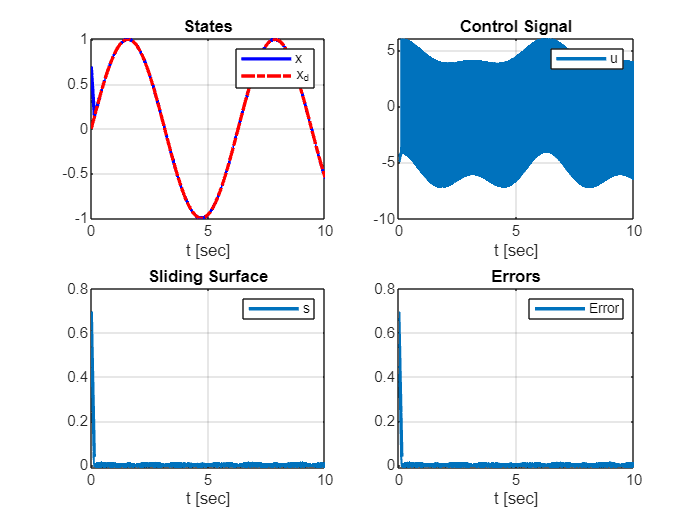

subplot(221)
plot(t, x, 'b', t, Traj.xd, 'r-.', 'LineWidth', 2)
grid on, legend('x', 'x_d'), title('States'), xlabel('t [sec]')

subplot(222)
plot(t, u, 'LineWidth', 2)
grid on, legend('u'), title('Control Signal'), xlabel('t [sec]')

subplot(223)
plot(t, s, 'LineWidth', 2)
grid on, legend('s'), title('Sliding Surface'), xlabel('t [sec]')

subplot(224)
plot(t, x - Traj.xd, 'LineWidth', 2)
grid on, legend('Error'), title('Errors'), xlabel('t [sec]')